clearvars
close all
clc

%% load audio
[x,Fs] = audioread('hw2_buongiorno.wav');
T = 1/Fs;
Nx = length(x);

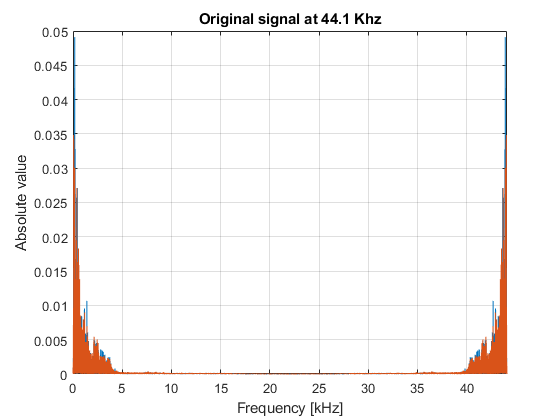


fx = (0:Nx-1)/(Nx*T);
X = T*fft(x);
% show absolute value in frequency
plot(fx/1e3,(abs(X)));
grid;
xlabel('Frequency [kHz]'); xlim([0 Fs/1e3]);
ylabel('Absolute value');
title('Original signal at '+ string(Fs/1e3) +' Khz');

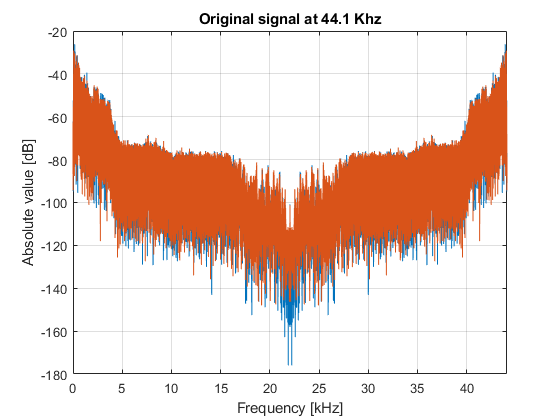


plot(fx/1e3,20*log10(abs(X)));
grid;
xlabel('Frequency [kHz]'); xlim([0 Fs/1e3]);
ylabel('Absolute value [dB]');
title('Original signal at '+ string(Fs/1e3) +' Khz');



[y1,Fs1] = resampling(x,Fs,4,3);

       22050



[y2,Fs2] = resampling(y1,Fs1,8,7);

       29400



[y3,Fs3] = resampling(y2,Fs2,5,7);

       24000



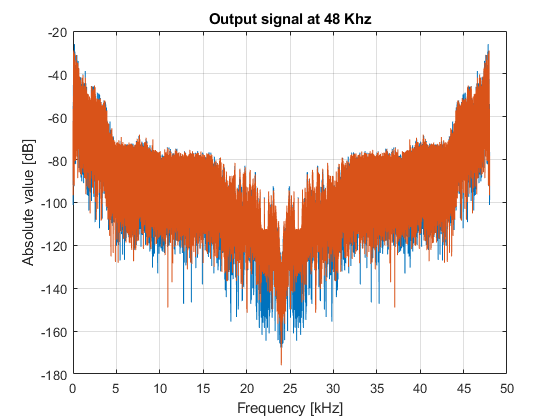

Ny3=length(y3);
T3 = 1/Fs3;
fy3 = (0:Ny3-1)/(Ny3*T3);
Y3 = T3*fft(y3);
% show absolute value in frequency
plot(fy3/1e3,20*log10(abs(Y3)));
grid;
xlabel('Frequency [kHz]'); 
ylabel('Absolute value [dB]');
title('Output signal at '+ string(Fs3/1e3) +' Khz');

sound(y3,Fs3);

#### Resampling function

function [y,Fs1] = resampling(x,Fs,L,M)
    T = 1/Fs;
    Nx=length(x);
    % Fs1 = (L/M)*Fs
    
    T2 = T/L;
    T1 = M*T2;
    Fs2 = 1/T2;
    Fs1 = 1/T1;
    
    Nv = L*Nx;
    v = zeros(Nv,2); % interpolated signal
    for l=0:Nx-1
        v(l*L+1,:) = L*x(l+1,:);
    end
    
    f0 = Fs/2 * min(1,L/M);
    disp(f0);
    al = 0.1; % transition bandwidth in percentage
    fp = f0; % pass band upper limit
    fs = f0*(1+al); % stop band lower limit
    
    [NN,Fo,Ao,W] = firpmord([fp fs],[1 0],[1e-3 1e-4],Fs2);
    h0 = firpm(NN,Fo,Ao,W);
    z = [conv(v(:,1),h0), conv(v(:,2),h0)];
    y = z(1:M:end,:);
    
end